# What should the basis functions be for fitting the raw lip signals?

We model the lip fluorescence in the 500-600nm band.  We find good fits to much of the data, after accounting for the presence of blood in the stromal layer.

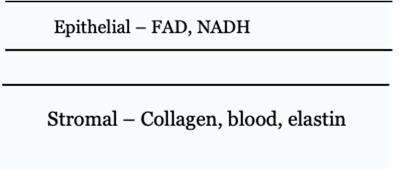

We experimented with various fluorophores.  Based on the anatomy, we apply blood transmittance to collagen and elastin, but not FAD. There are notes about what we tried below, but the main conclusion is that collagen through blood plus FAD does a good job for the lip. When we included elastin, it was never used by the fitting algorithm.  

These are measurements with different excitation lights at max intensity.  All the subjects show the peak shift from 500 to 515 as the excitation light changes from 405 to 450.

Also, notice the very large dip on the lip around 580, but not on the tongue. 

Something to remember when we write.  When you measure samples, or with an endoscope, you may be able to see different fluorophores.  The global (raw) signal, however, may be dominated by one of the fluorophores with only relatively small contributions from the others.  In this case, it appears that collagen through oxygen is the dominant signal in 500-600 band.

We still have things we will try with Keratin, maybe some deoxy.  But we are pretty darn close and it is enough for an image systems definition to find the standard values.  The regularity in the data alone across the subjects and levels is enough.  These comments apply to both the Lip and Tongue data at all excitation wavelengths.

3/4 of the blood is oxygenated.  When we go deeper, we might see the effects of deoxy.  To examine that idea, we might apply the deoxy transmittance to collagen as well, we added that in as an additional column vector in the fluorophore basis.  We let the lsnoneg fit choose how much it wanted of the two types of collagen transmittances.  For the lip data, the deoxy didn't really change anything.

**Caution: ** We have multiple data sets describing the emissions of each of these fluorophores in the isetfluorescence repository.  The literature does not always agree on the emission matrix. 

## Programming notes

**Repositories**: isetcam, isetfluorescence and oe_tongue_lip

To support the calculations of absorbance and transmittance we created a Matlab class called 'medium', which helps us keep track of the relationship between absorbance, absorptance, transmittance and optical density.

## Initialize parameters

Different analyses are based on different wavebands.

ieInit;
wave = 500:600;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:20;
[T,dataDir] = oeDatabaseCreate;

## Select the fluorophores 

We create the base fluorophore emissions matrix.  It does not include blood (fluorophoresB).  Below, we sweep through different potential levels of blood optical density, checking how well the modified fluorophore matrix predicts the data samples.  Notice that the effective optical density of blood can depend on the wavelength of the excitation light.  Some lights will penetrate into the skin (substrate) more deeply than others, thus creating a longer path through the blood.

We tried many fluorophore files from the literature. These are described in in **s_oeFluorophoreEmissions.mlx**.  

Apart from FAD, all of the fluorophore emission spectra decline in the wave band from 500-600nm.  They exact emissions differ between labs, but the slopes are similar.

For the lip, there is no keratin, porphyrins, or chlorophyll.  We selected which to use in the s_oeBloodFluorophoreBasis.mlx script.

Here are notes about things we tried.

- fluorophoreNames = {'CollagenWuQu','NADH_webfluor','FADLin'};

- fluorophoreNames = {'CollagenWuQu','FADLin'}; 

- fluorophoreNames = {'CollagenWuQu','FADValdez'};

- fluorophoreNames = {'CollagenWuQu','FAD_webfluor'};

- fluorophoreNames = {'CollagenWuQu','elastin_webfluor','FADValdez'};

- fluorophoreNames = {'collagen7','elastin_webfluor','FADValdez'};

- fluorophoreNames = {'collagen1','elastin_webfluor','FAD_webfluor','NADH_webfluor'};

- fluorophoreNames = {'collagen1'};   % Interesting, but not great

- fluorophoreNames = {'elastin_webfluor','FADValdez'}; 

- fluorophoreNames = {'elastin_webfluor'};  

We should also try deoxygenated blood at some point.

## Create fluorophore matrix and read database

fluorophoreNamesB = {'collagen1','FAD_webfluor'};
[fluorophoresB,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## 405/415 nm excitation

The logic is to read all the data for each subject at both 405 nm and 415 nm, and at all intensity levels. The data from different days are sometimes from different locations.

subjects = {'Z','B','D','J'};

% Here is oxy
% https://omlc.org/spectra/hemoglobin/summary.html
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);

rmse = zeros(size(subjects));
odError = zeros(numel(odLevels),numel(subjects));
ods = zeros(numel(subjects),1);    

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    lipData  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);   
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,lipData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 8.00
OD across subjects for 405/415nm 7.00
OD across subjects for 405/415nm 5.00
OD across subjects for 405/415nm 5.00


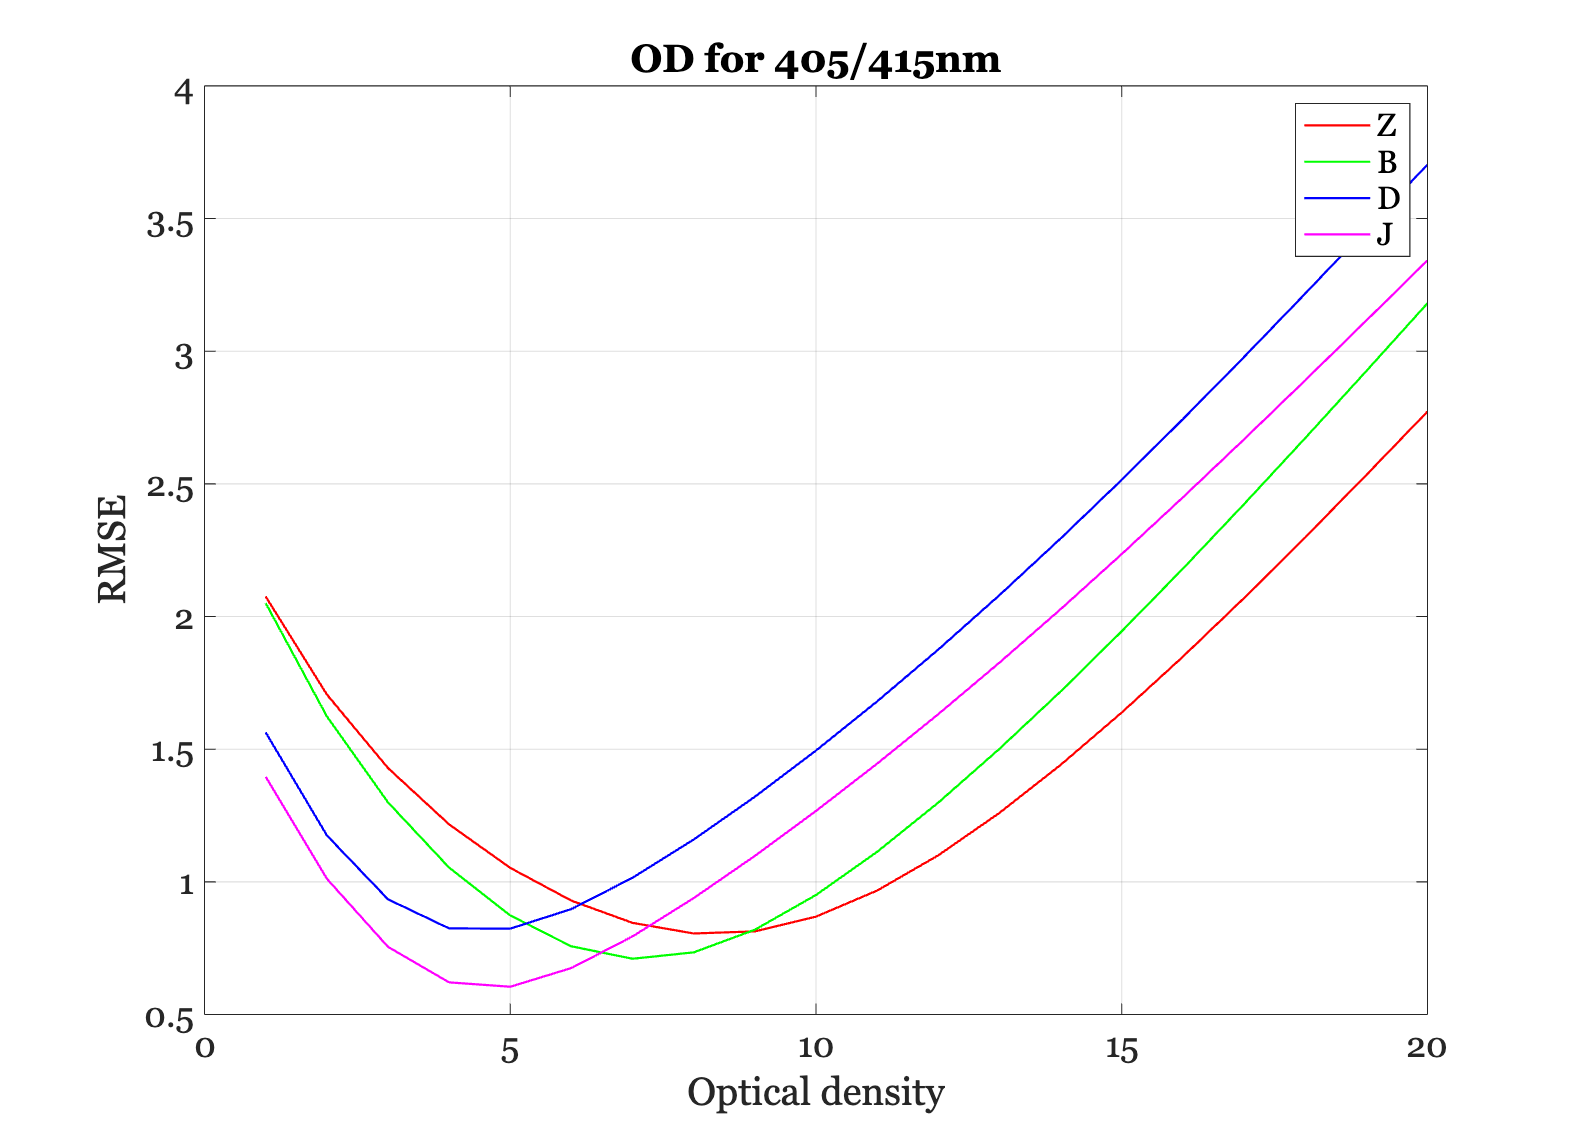


% Plot the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError);
grid on; title('OD for 405/415nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## Apply the estimated optical density and fit the fluorescence data

The fits with oxy applied to the collagen are great.

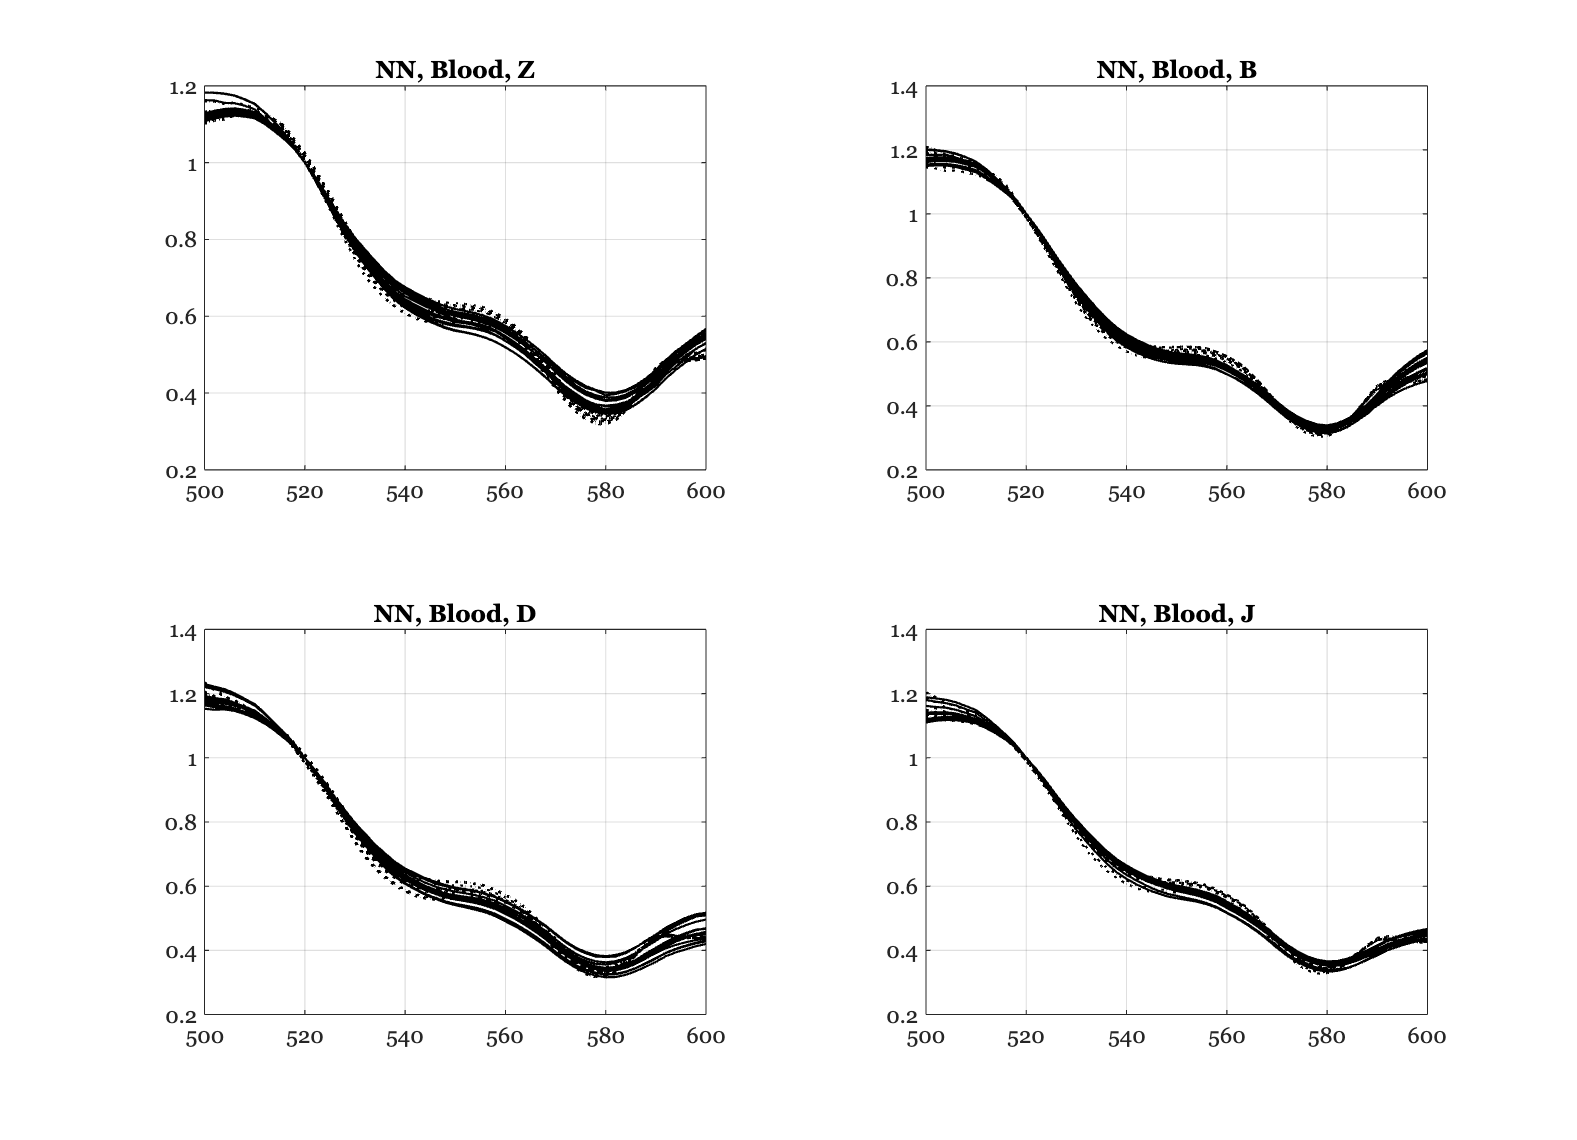

Subject Z
   14.9808   14.0917   15.0355   13.7928   14.1384   13.3794   13.2571   13.9409   13.9495   14.3170   14.3080   13.5996   13.3658   13.1200
    0.5266    0.5665    0.5238    0.5692    0.5515    0.5907    0.5997    0.5609    0.5632    0.5464    0.5461    0.5853    0.6007    0.6103

Subject B
   14.9277   14.6990   15.1919   13.5934   14.0527   14.7943   14.7301   13.8287   13.8532   14.7330   14.6474   14.4276   14.6260
    0.4703    0.4650    0.4467    0.5088    0.4891    0.4714    0.4750    0.5034    0.5028    0.4641    0.4697    0.4860    0.4693

Subject D
   13.2433   13.3970   13.3084   11.8622   11.8805   12.4448   12.5103   12.6904   12.4442   12.6136   12.1357   12.3687   12.5164   12.6949
    0.4003    0.3907    0.3977    0.4893    0.4858    0.4443    0.4427    0.4335    0.4441    0.4445    0.4682    0.4481    0.4384    0.4280

Subject J
   12.6869   12.2943   11.6916   11.0671   11.1038   11.5133   11.4732   11.1763   11.0959   11.4945   11.4205   11.4718   11.4348 


ieFigure;
tiledlayout(2,2);

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);

    lipData = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);

    oxyblood.opticalDensity = ods(ii);
    [fluorophores,fluorophoreNames] = oeApplyBlood(fluorophoresB,fluorophoreNamesB,oxyblood);
    wgtsNN = zeros(size(fluorophores,2),size(lipData,2));

    for dd = 1:size(lipData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
    end
    d = lipData - fluorophores*wgtsNN;
    rmse(ii) = norm(d(:),2);
    
    nexttile
    plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

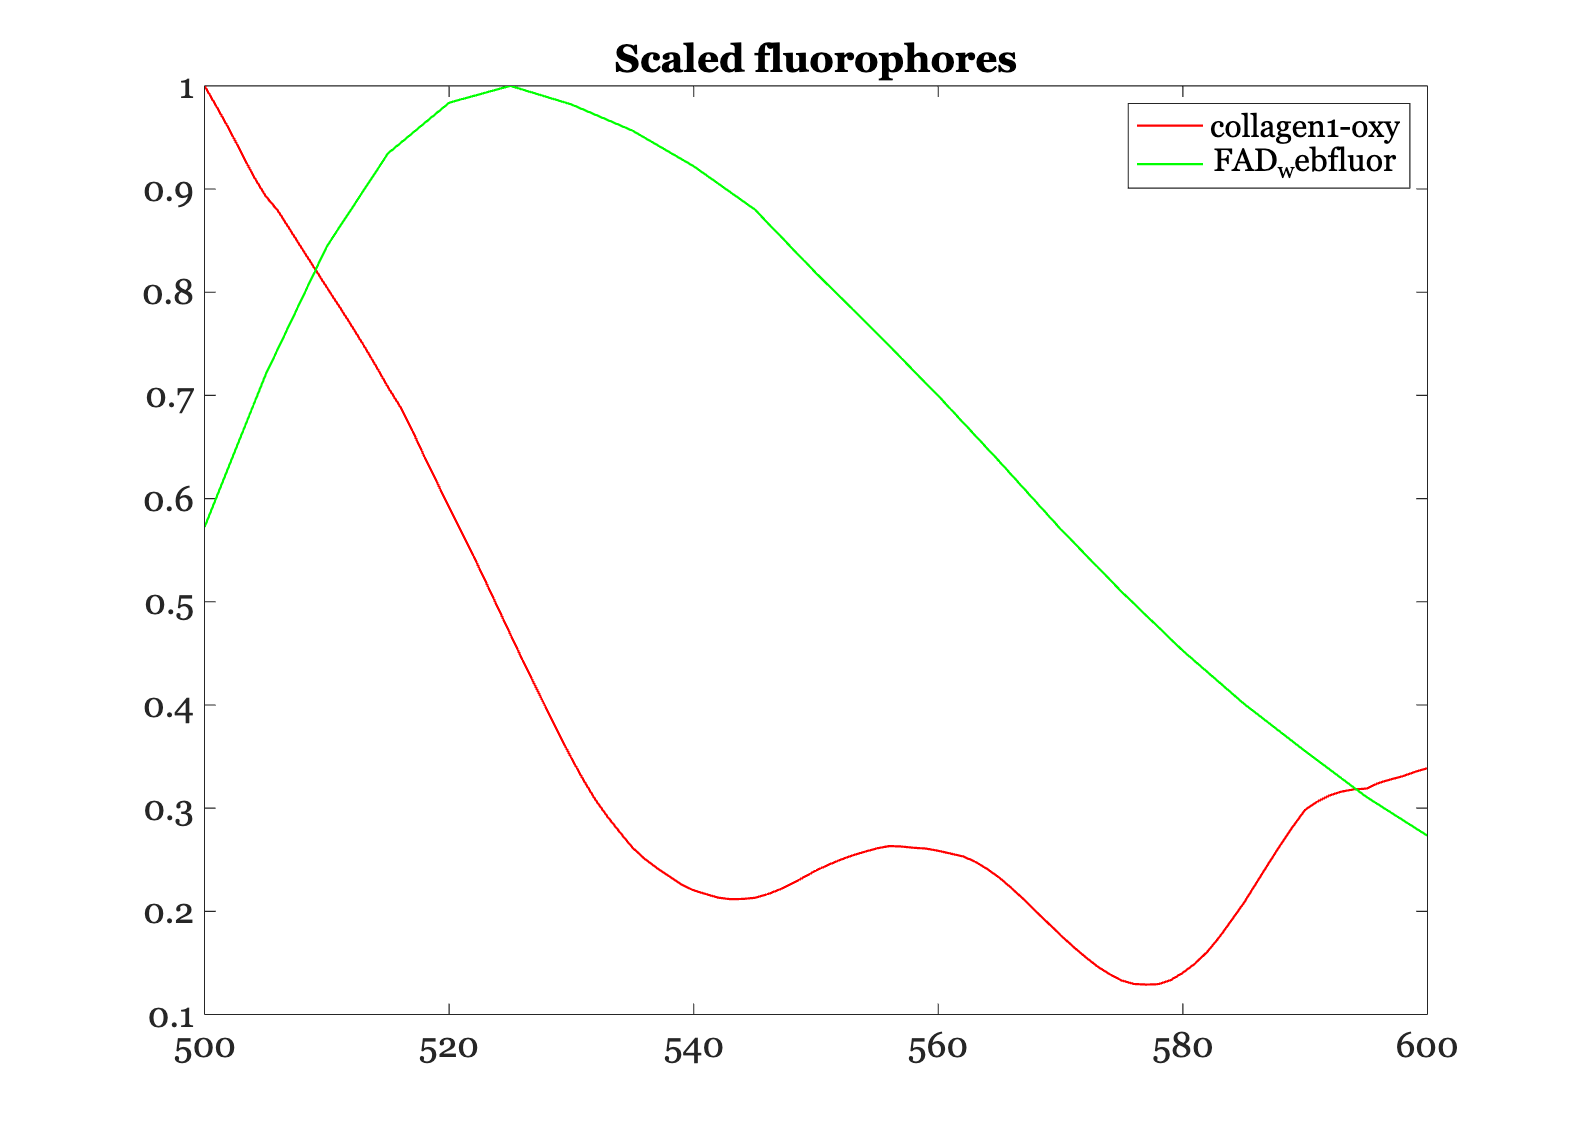


ieFigure; 
mx = max(fluorophores);
plot(wave,fluorophores*diag(1./mx));
title('Scaled fluorophores');
legend(fluorophoreNames);


disp(rmse)

    0.8056    0.7103    0.8238    0.6048



## Create 450 nm blood optical density levels

The 450 nm light OD seems to be a bit different, which we explain by saying this wavelength penetrates a bit deeper into the skin.  This makes us wonder whether we need some deoxygenated blood included.

odError = zeros(numel(odLevels),numel(subjects));

for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},...
        'substrate','lip',...
        'e wave',450);
    lipData = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);    
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,lipData,wave,odLevels);
end
fprintf('OD across subjects for 450nm %.2f\n',ods);

OD across subjects for 450nm 15.00
OD across subjects for 450nm 16.00
OD across subjects for 450nm 10.00
OD across subjects for 450nm 13.00


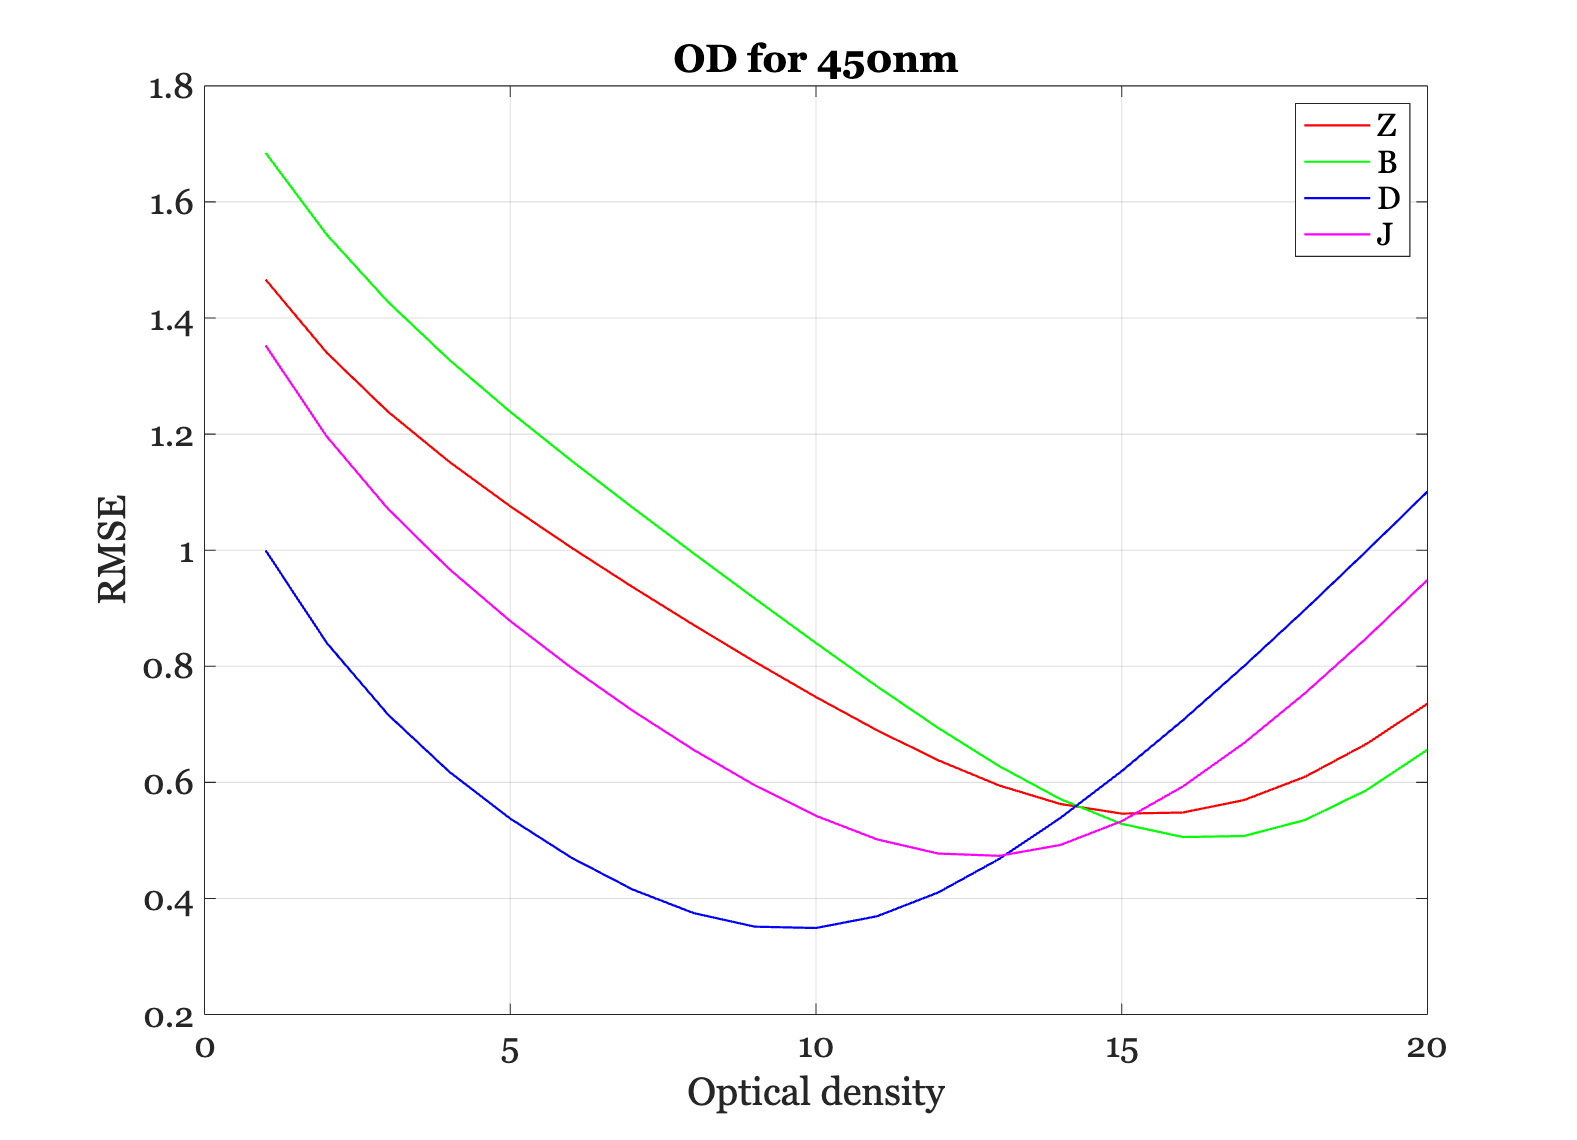

ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 450nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');  

## 450 nm excitation light

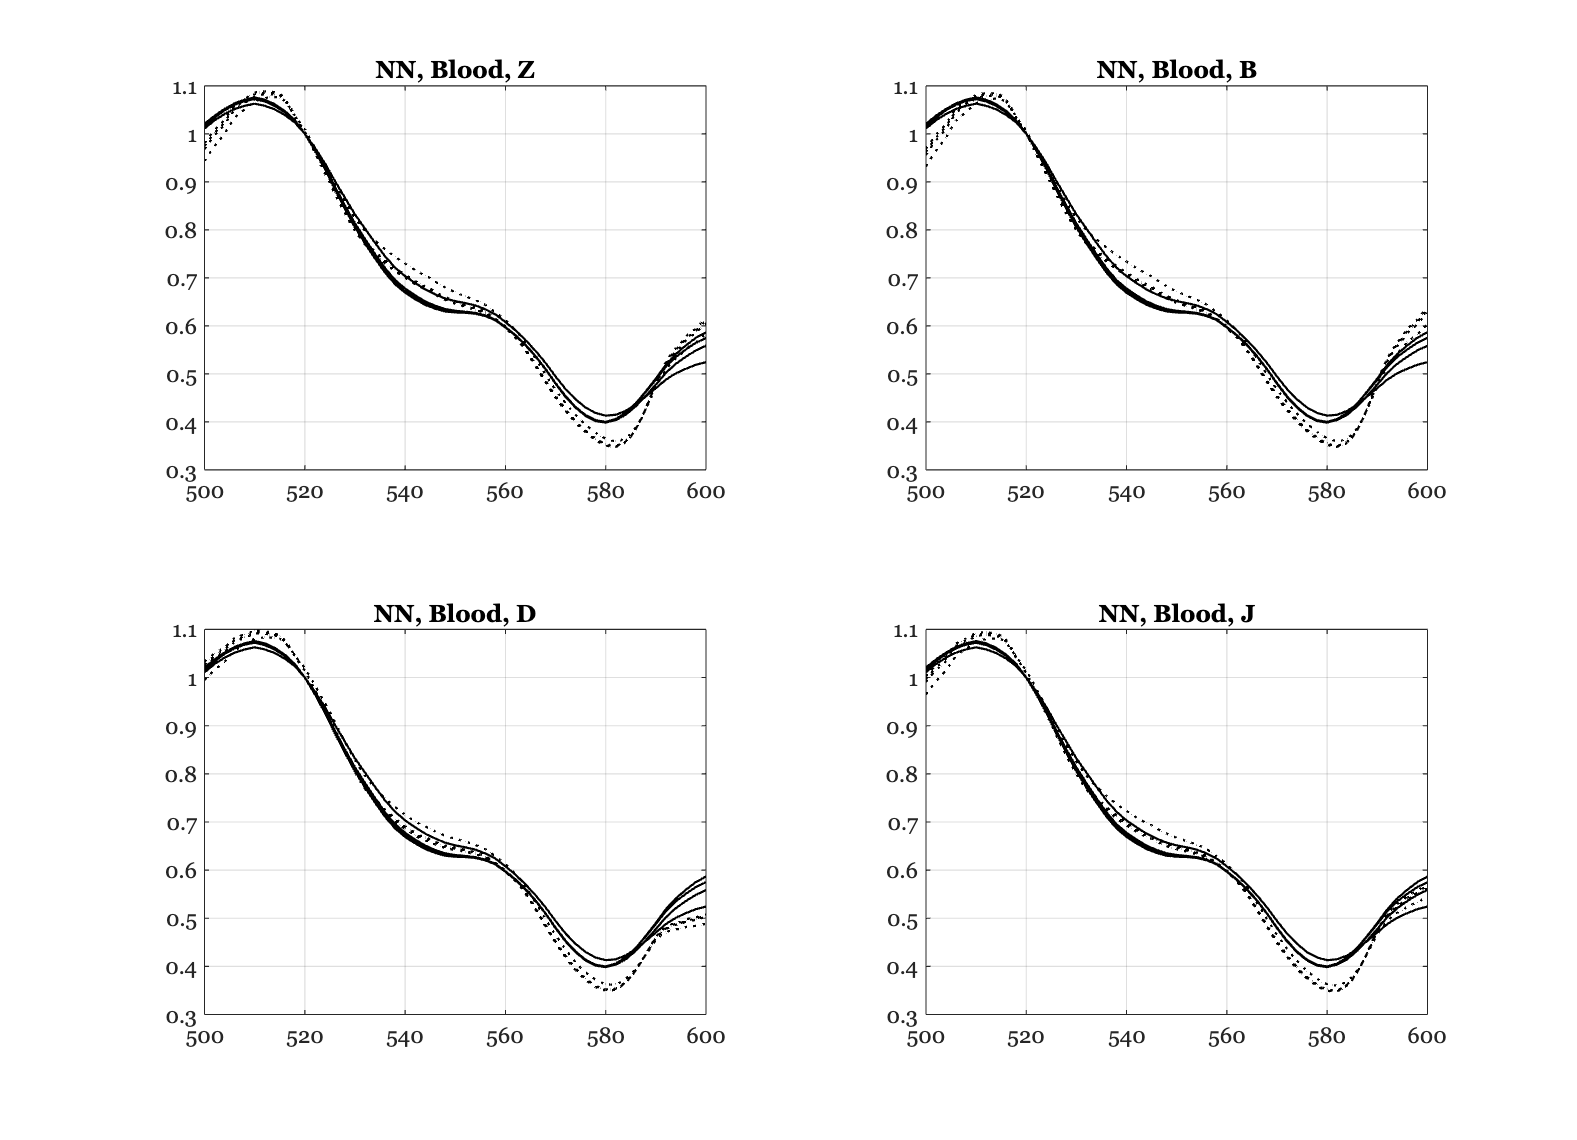

Subject Z
   18.1946   18.4710   16.8551   18.7592
    0.7349    0.7310    0.7622    0.7266

Subject B
   19.3082   19.6152   17.8741   19.9270
    0.7446    0.7407    0.7713    0.7363

Subject D
   13.3317   13.4887   12.3931   13.6811
    0.6753    0.6714    0.7061    0.6664

Subject J
   16.0919   16.3141   14.9278   16.5596
    0.7139    0.7100    0.7424    0.7053



ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)

    oxyblood.opticalDensity = ods(ii);
    [fluorophores, fluorophoreNames] = oeApplyBlood(fluorophoresB,fluorophoreNamesB,oxyblood);
    wgtsNN = zeros(size(fluorophores,2),size(lipData,2));

    for dd = 1:size(lipData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
    end
    d = lipData - fluorophores*wgtsNN;
    rmse(ii) = norm(d(:),2);

    nexttile
    plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

disp(rmse);

    0.5331    0.5929    0.5424    0.4735



disp(fluorophoreNames'); 

    {'collagen1-oxy'}
    {'FAD_webfluor' }



## Once more with deoxy

There is no real value add in this case for putting in a lot or a little deoxy.  We tried OD of 5, 30, and 60.  We could see the weights changing but not the RMSE.  Two of the subjects don't use the deoxy at all in any case.

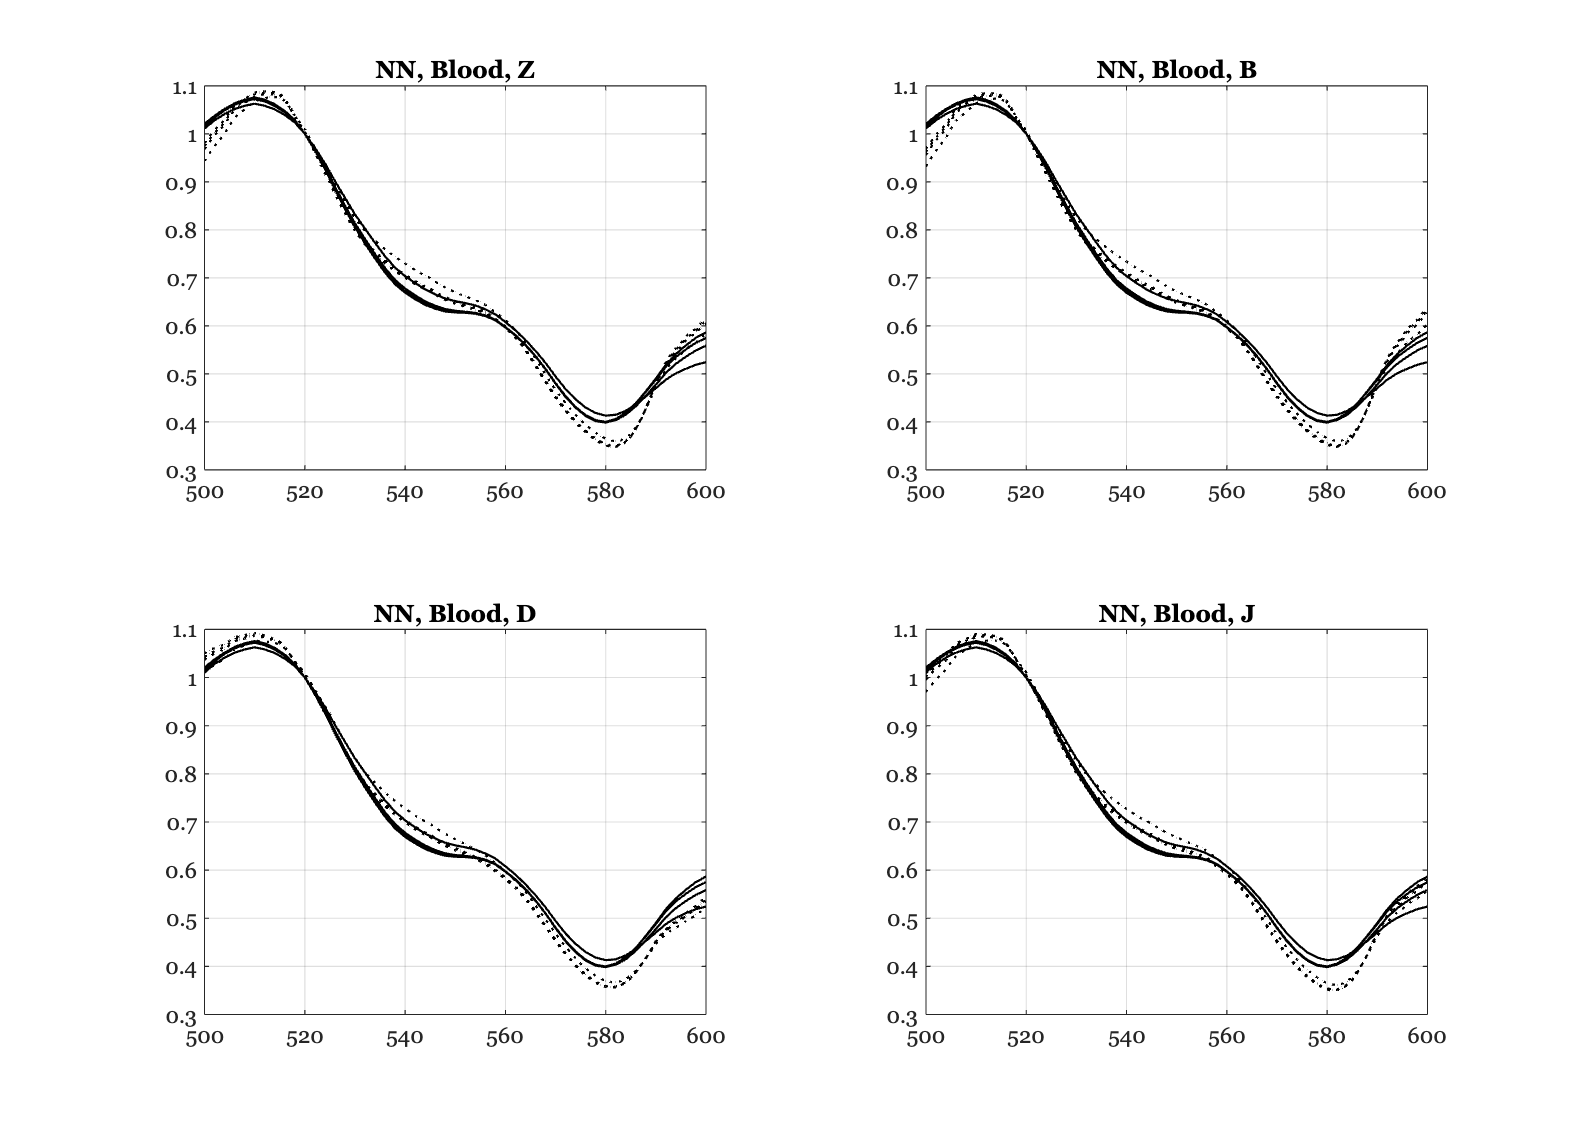

Subject Z
   18.1946   18.4710   16.8551   18.7592
    0.7349    0.7310    0.7622    0.7266
         0         0         0         0

Subject B
   19.3082   19.6152   17.8741   19.9270
    0.7446    0.7407    0.7713    0.7363
         0         0         0         0

Subject D
    5.4779    5.5037    4.5664    5.1674
    0.7079    0.7046    0.7386    0.7018
   12.0277   12.2288   11.9864   13.0385

Subject J
   12.9733   12.9506   11.5457   12.5449
    0.7218    0.7185    0.7510    0.7155
    4.8389    5.2190    5.2478    6.2295



deoxyblood = medium('deoxy_molarExtinctionCoefficient.mat','wave',wave);
deoxyblood.opticalDensity = 5;
%{
ieFigure;
plot(wave,deoxyblood.transmittance,'b-',wave,oxyblood.transmittance,'r-');
%}

ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)

    oxyblood.opticalDensity = ods(ii);
    [fluorophores, fluorophoreNames] = oeApplyBlood(fluorophoresB,fluorophoreNamesB,...
        oxyblood, ...
        'deoxy',deoxyblood);

    wgtsNN = zeros(size(fluorophores,2),size(lipData,2));

    for dd = 1:size(lipData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
    end
    d = lipData - fluorophores*wgtsNN;
    rmse(ii) = norm(d(:),2);

    nexttile
    plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

disp(rmse)

    0.5331    0.5929    0.5021    0.4676



disp(fluorophoreNames'); 

    {'collagen1-oxy'  }
    {'FAD_webfluor'   }
    {'collagen1-deoxy'}

